# Example 8.2: `Airborne ``Datalink` `DF`

Nicholas O'Donoughue 1 July 2019

*At what range is the angular accuracy, as bounded by the CRLB, of an array-based AOA estimate better than *$$0.5^\circ$$* RMSE for sources near broadside (*$$\psi \approx 0$$*), given the source parameters in Table 8.2?*

## Solution

First, let us define the parameters

% Define transmitter values
Pt =     100;
Gt =     0;
Bs_kHz = 500;
Bs = Bs_kHz * 1e3;
f0_MHz = 950;
f0 = f0_MHz * 1e6;
Lt =     3;
ht =     5e3;
theta =  5;
% Optionally, we can define theta to be a vector of random positions, for a
% multi-source problem. Just uncomment the following line.
% theta = [0 30 60]+rand(1,3)/10;
psi = theta*pi/180;

% Define receiver values
d_lam =          .5;
N =              5;
Gr =             0;
Lr =             2;
Fn =             4;
Bn_MHz =         100;
Bn = Bn_MHz * 1e6;
hr =             10;
T_microseconds = 1;
T = T_microseconds*1e-6;

We begin by computing the received power as a function of range, using the same techniques from Chapter 2.

% Compute the number of snapshots
t_samp = 1/(2*f0);
M = floor(T/t_samp);

Next, we generate function handles for the array factor and derivative of the array factor.

% Generate the array factor
[v,v_dot] = array.make_steering_vector(d_lam,N);

In this block of code, we compute the received SNR from the transmitter and receiver parameters, at a series of ranges.

% Generate received signal power and SNR at multiple ranges
R_min_km =  100;
R_step_km = 20;
R_max_km =  500;
R = (R_min_km:R_step_km:R_max_km)*1e3;
Lprop = prop.pathLoss(R,f0,ht,hr,false);
Pr_dB = 10*log10(Pt) + Gt + Gr - Lt - Lr - Lprop;
N_dB = 10*log10(utils.constants.kT*Bn) + Fn;
xi_dB = Pr_dB-N_dB;
xi_lin = 10.^(xi_dB/10);

We compute the CRLB for each range. This can be done with a for loop or, more compactly, with the built-in arrayfun command. This process is repeated for the stochastic CRLB as well. 

% Compute CRLB
C_psi = zeros(numel(xi_dB),1);
C_psi_stoch = zeros(numel(xi_dB),1);

for idx_xi = 1:numel(xi_dB)
    C_psi(idx_xi) = array.crlb_det(xi_lin(idx_xi),1,psi,M,v,v_dot);
    C_psi_stoch(idx_xi) = array.crlb_stochastic(xi_lin(idx_xi),1,psi,M,v,v_dot);
end
C_th = (180/pi)^2*C_psi;
RMSE_th = sqrt((C_th));
C_th_stoch =(180/pi)^2*C_psi_stoch;
RMSE_th_stoch = sqrt((C_th_stoch));

The following snippet executes a Monte Carlo trial.  To deactivate it, uncheck the box for `do_mc_trial`.  Experiment with the Monte Carlo trial by changing the number of trials to run and observing the outputs.  As nMC increases beyond 100, you should start to observe stable results in the output.

% Compute MC Experiment
do_mc_trial = true;
nMC = 100;

if do_mc_trial
    s = sqrt(1/2)*(randn(M,nMC)+1i*randn(M,nMC));
    n = sqrt(1/2)*(randn(N,M,nMC)+1i*randn(N,M,nMC));
    
    nR = numel(R);
    nP = numel(psi)
    RMSE_th_beam = zeros(nR,nP);
    RMSE_th_mvdr = zeros(nR,nP);
    RMSE_th_music = zeros(nR,nP);
    fprintf('Executing array DF monte carlo trial...\n\t');
    tStart = tic;
    for idxR = 1:nR
        fprintf('.');
        if mod(idxR,40)==0
            fprintf('(%d/%d)\n',idxR,nR);
        end
        thisS = s*sqrt(10.^(xi_dB(idxR)/10));
        
        for idxPsi = 1:numel(psi)
            
            thisX = v(psi(idxPsi)).*reshape(thisS,1,M,nMC) + n;
            
            this_err_beamscan = zeros(1,nMC);
            this_err_mvdr = zeros(1,nMC);
            this_err_music = zeros(1,nMC);
            for idxMC=1:nMC
                % Compute beamscan image
                [P,psi_vec] = array.beamscan(thisX(:,:,idxMC),v,pi/2,2001);
                [~,idx_pk] = max(abs(P));
                this_err_beamscan(idxMC) = abs(psi_vec(idx_pk)-psi(idxPsi));
                
                % Compute beamscan image
                [P_mvdr,psi_vec] = array.beamscan_mvdr(thisX(:,:,idxMC),v,pi/2,2001);
                [~,idx_pk] = max(abs(P_mvdr));
                this_err_mvdr(idxMC) = abs(psi_vec(idx_pk)-psi(idxPsi));
                
                % Compute beamscan image
                [P_music,psi_vec] = array.music(thisX(:,:,idxMC),v,1,pi/2,2001);
                [~,idx_pk] = max(abs(P_music));
                this_err_music(idxMC) = abs(psi_vec(idx_pk)-psi(idxPsi));
            end
            
            % Average Results
            RMSE_th_beam(idxR,idxPsi) = (180/pi)*sqrt(sum(this_err_beamscan.^2)/nMC);
            RMSE_th_mvdr(idxR,idxPsi) = (180/pi)*sqrt(sum(this_err_mvdr.^2)/nMC);
            RMSE_th_music(idxR,idxPsi) = (180/pi)*sqrt(sum(this_err_music.^2)/nMC);
            
        end
    end  
    fprintf('done.\n');
    tElapsed = toc(tStart);
    hrs = floor(tElapsed/3600);
    mins = floor((tElapsed-hrs*3600)/60);
    secs = tElapsed - 60*mins - 3600*hrs;
    fprintf('Elapsed time: %d hours, %d minutes, %.2f seconds\n',hrs,mins,secs);
else
    % If we didn't do the MC trial, define the output vectors with NaNs, so
    % that they don't show up on the plot, but also don't throw an error.
    RMSE_th_beam = nan*ones(size(R));
    RMSE_th_mvdr = nan*ones(size(R));
    RMSE_th_music = nan*ones(size(R));
end

Executing array DF monte carlo trial...
	

.....................

done.


Elapsed time: 0 hours, 2 minutes, 16.97 seconds


The results are plotted, along with a Monte Carlo experiment against range in Figure 8.13, which shows that the RMSE achieves $$0.5^\circ$$ accuracy when the range to the target drops below $$\approx 425$$ km.

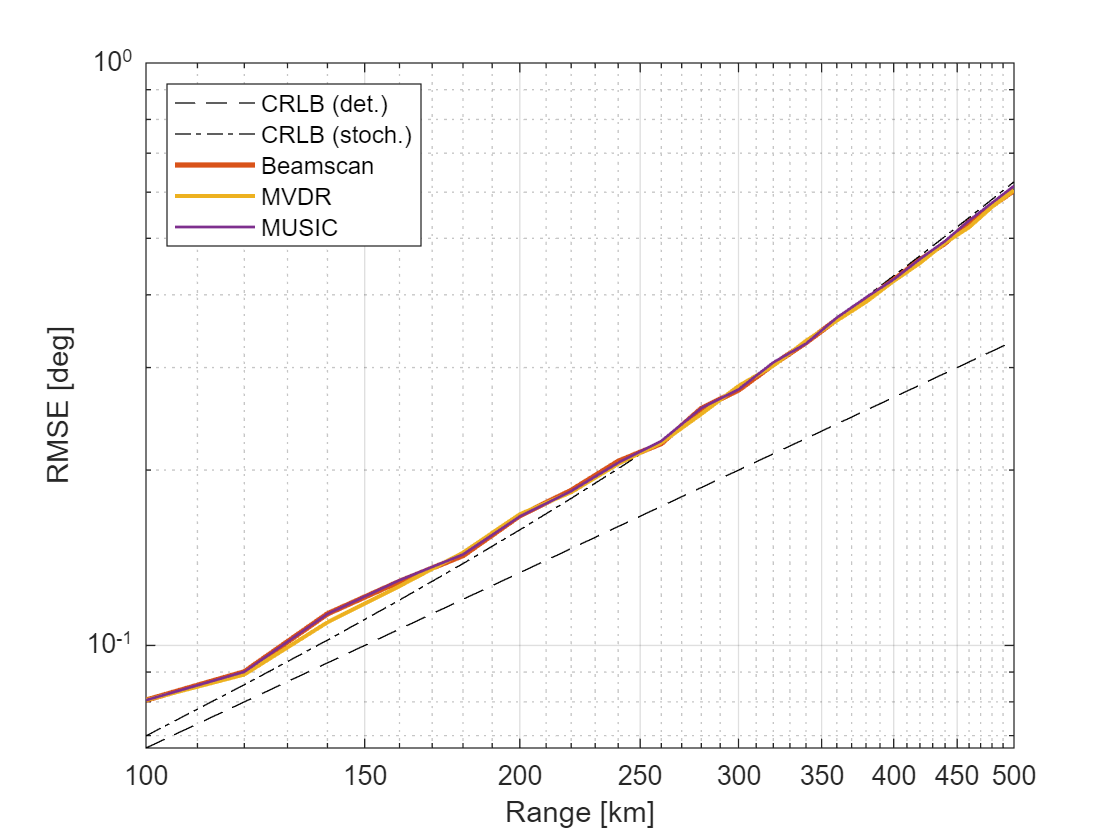

% Plot results
figure;
loglog(R/1e3,RMSE_th,'k--','DisplayName','CRLB (det.)');
hold on;
loglog(R/1e3,RMSE_th_stoch,'k-.','DisplayName','CRLB (stoch.)');
set(gca,'ColorOrderIndex',2);
plot(R/1e3,RMSE_th_beam,'LineWidth',2,'DisplayName','Beamscan');
plot(R/1e3,RMSE_th_mvdr,'LineWidth',1.5,'DisplayName','MVDR');
plot(R/1e3,RMSE_th_music,'LineWidth',1,'DisplayName','MUSIC');
xlabel('Range [km]');
ylabel('RMSE [deg]');
grid on;
legend('Location','NorthWest')